%--------------------------------------------------------------- 1
% Sumamos todos los vectores y dividimos por 10 para obtener el vector 
% promedio 𝑚, que representa la cara promedio.
E1 =1

E1 = 1

% Definir las matrices
p1 = [0.1 0.3 0.4; 0.2 0.1 0.5; 0.3 0.3 0.8];
p2 = [0.1 0.1 0.2; 0.1 0.7 0.3; 0.4 0 0.84];
p3 = [0.6 0.3 0.8; 0.1 0.4 0.3; 0 0.3 0.52];
p4 = [0.54 0.2 0; 0.1 0.1 0.4; 0.4 0.2 0.6];
p5 = [0.8 0.1 0.3; 0.24 0 0.7; 0.32 0.3 0];
p6 = [0.14 0 0.5; 0 0.25 0.4; 0.1 0.2 0.7];
p7 = [0.45 0.3 0; 0.3 0.1 0.5; 0.2 0.4 0.6];
p8 = [0.6 0.3 0.3; 0.35 0 0.5; 0.1 0.6 0.5];
p9 = [0.5 0.2 0.1; 0.24 0 0.6; 0.9 0.2 0.7];
p10 = [0.63 0.5 0; 0.3 0.2 0.7; 0.4 0.2 0.8];

% Convertir las matrices en vectores columna
p1 = p1(:);
p2 = p2(:);
p3 = p3(:);
p4 = p4(:);
p5 = p5(:);
p6 = p6(:);
p7 = p7(:);
p8 = p8(:);
p9 = p9(:);
p10 = p10(:);

% Calcular la media
m = (p1 + p2 + p3 + p4 + p5 + p6 + p7 + p8 + p9 + p10) / 10;

% Mostrar el vector promedio
disp('El vector promedio m es:');

El vector promedio m es:


disp(m);

    0.4460
    0.1930
    0.3120
    0.2300
    0.1850
    0.2700
    0.2600
    0.4900
    0.6060




%--------------------------------------------------------------- 2
E2 =2

E2 = 2

% Calcular los vectores de caricatura
q1 = p1 - m;
q2 = p2 - m;
q3 = p3 - m;
q4 = p4 - m;
q5 = p5 - m;
q6 = p6 - m;
q7 = p7 - m;
q8 = p8 - m;
q9 = p9 - m;
q10 = p10 - m;

% Comprobar que la suma de los vectores de caricatura es cero
sum_q = q1 + q2 + q3 + q4 + q5 + q6 + q7 + q8 + q9 + q10;
is_zero = all(sum_q(:) == 0);

% Mostrar el resultado
disp('La suma de los vectores de caricatura es:');

La suma de los vectores de caricatura es:


disp(sum_q);

   1.0e-15 *

   -0.6106
   -0.1110
    0.1665
    0.1665
    0.1110
   -0.7216
    0.1110
   -0.5551
    0.1110



disp('¿Es la suma igual a cero?');

¿Es la suma igual a cero?


disp(is_zero);

   0



%Calcular los vectores de caricatura: Restamos el vector promedio 𝑚 de cada vector 
%p𝑖 para obtener los vectores de caricatura qi

%Comprobar la suma: Sumamos todos los vectores qi
% y verificamos que la suma es cero.

% Calcular los vectores de caricatura
q1 = p1 - m;
q2 = p2 - m;
q3 = p3 - m;
q4 = p4 - m;
q5 = p5 - m;
q6 = p6 - m;
q7 = p7 - m;
q8 = p8 - m;
q9 = p9 - m;
q10 = p10 - m;

% Comprobar que la suma de los vectores de caricatura es cero
sum_q = q1 + q2 + q3 + q4 + q5 + q6 + q7 + q8 + q9 + q10;
is_zero = all(sum_q(:) == 0);

% Mostrar el resultado
disp('La suma de los vectores de caricatura es:');

La suma de los vectores de caricatura es:


%0 
% Esto confirma que los vectores de caricatura están centrados alrededor
% de la media, lo que es una propiedad esperada y deseada en el análisis
% de componentes principales (PCA).
disp(sum_q);

   1.0e-15 *

   -0.6106
   -0.1110
    0.1665
    0.1665
    0.1110
   -0.7216
    0.1110
   -0.5551
    0.1110



disp('¿Es la suma igual a cero?');

¿Es la suma igual a cero?


%0 
%Esto confirma que los vectores de caricatura son linealmente dependientes 
% y que el subespacio 𝑆 abarcado por estos vectores tiene una dimensión 
% máxima de 9, como se mencionó en el documento.

disp(is_zero);

   0



%--------------------------------------------------------------- 3

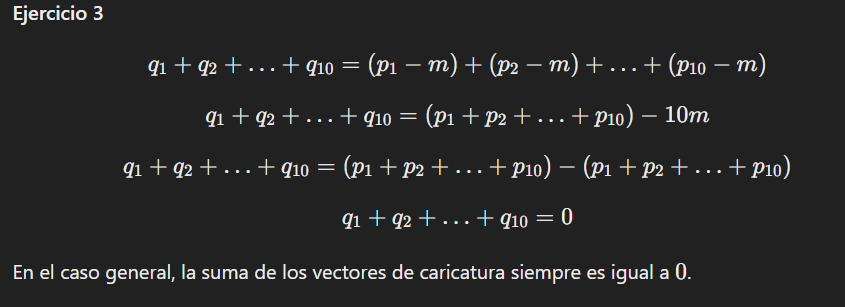

E3=3

E3 = 3

% Demostración teórica en MATLAB
% Recordemos que q_i = p_i - m y m = (p1 + p2 + ... + p10) / 10

% Suma de los vectores de caricatura
sum_q_general = (p1 - m) + (p2 - m) + (p3 - m) + (p4 - m) + (p5 - m) + ...
                (p6 - m) + (p7 - m) + (p8 - m) + (p9 - m) + (p10 - m);

% Simplificación
sum_q_general = (p1 + p2 + p3 + p4 + p5 + p6 + p7 + p8 + p9 + p10) - 10 * m;

% Sustituyendo m
sum_q_general = (p1 + p2 + p3 + p4 + p5 + p6 + p7 + p8 + p9 + p10) - ...
                (p1 + p2 + p3 + p4 + p5 + p6 + p7 + p8 + p9 + p10);

% Resultado final
sum_q_general = 0;

% Mostrar el resultado
disp('La suma de los vectores de caricatura en el caso general es:');

La suma de los vectores de caricatura en el caso general es:


disp(sum_q_general);

     0




%la suma de los vectores de caricatura sea 0 en el caso general confirma 
% que hemos centrado correctamente los datos alrededor de la media y que 
% los vectores de caricatura son linealmente dependientes.

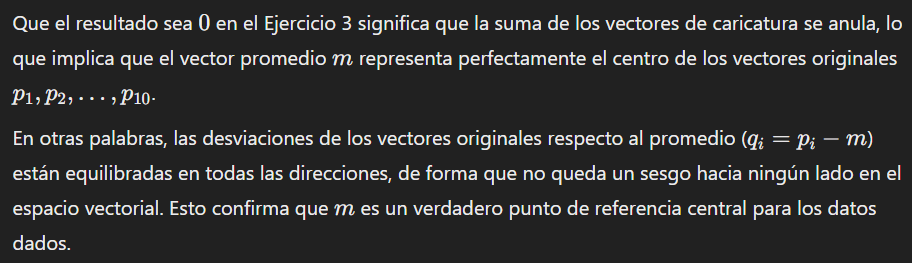    


E4=4

E4 = 4

% 
% Formar la matriz Q
% Crear la matriz Q (cada columna es un vector de caricatura)
Q = [q1, q2, q3, q4, q5, q6, q7, q8, q9, q10];

% Calcular la matriz de correlación C usando la definición
C = Q * Q';

% Verificar propiedades de C
is_symmetric = isequal(C, C');  % La matriz debe ser simétrica
eig_values = eig(C);            % Calcular los valores propios para verificar semidefinida positiva
is_positive_semidefinite = all(eig_values >= 0);

% Mostrar resultados
disp('La matriz de correlación C es:');

La matriz de correlación C es:


disp(C);

    0.5514    0.1292    0.0165    0.1122   -0.2451    0.1478   -0.0796    0.1726   -0.3808
    0.1292    0.1152    0.0456    0.0931   -0.1270    0.0989   -0.1208    0.1013   -0.0506
    0.0165    0.0456    0.5690   -0.0056   -0.1022   -0.1564   -0.3452    0.1352    0.1153
    0.1122    0.0931   -0.0056    0.1810   -0.0555    0.0690   -0.0780    0.0630    0.0762
   -0.2451   -0.1270   -0.1022   -0.0555    0.4402   -0.1995    0.1440   -0.1965    0.2099
    0.1478    0.0989   -0.1564    0.0690   -0.1995    0.2210    0.0480    0.0470   -0.1402
   -0.0796   -0.1208   -0.3452   -0.0780    0.1440    0.0480    0.6040   -0.1540   -0.1016
    0.1726    0.1013    0.1352    0.0630   -0.1965    0.0470   -0.1540    0.1890   -0.1114
   -0.3808   -0.0506    0.1153    0.0762    0.2099   -0.1402   -0.1016   -0.1114    0.5336



disp('¿Es C simétrica?');

¿Es C simétrica?


disp(is_symmetric);

   1



disp('¿Es C semidefinida positiva?');

¿Es C semidefinida positiva?


disp(is_positive_semidefinite);

   1





% Mostrar la matriz C La 
% representa la correlación entre las dimensiones de los vectores de caricatura. 
% Es simétrica y semidefinida positiva, propiedades que confirman que puede usarse
% en el Análisis de Componentes Principales (PCA) para determinar las direcciones principales.